décompression des données ECG

unzip(fullfile('physionet_ECG_data','ECGData.zip'))

Error using checkfilename>validateFilename
Function UNZIP was unable to find file ''physionet_ECG_data/ECGData.zip''.

Error in checkfilename (line 49)
[fullfilename, fid] = validateFilename( ...

Error in parseUnArchiveInputs (

% unzip(fullfile('physionet_ECG_data','ECGData.zip'),...
%     fullfile('physionet_ECG_data-main'))
load(fullfile('googlenet/ECGData.mat'))


parentDir = '/Users/Arthur1/Desktop/ESIEE/Cours/E4/S2/Projet IHM';
dataDir = 'data';
helperCreateECGDirectories(ECGData,parentDir,dataDir)

Unrecognized function or variable 'helperCreateECGDirectories'.

Plot des ECGs

helperPlotReps(ECGData)

Unrecognized function or variable 'helperPlotReps'.

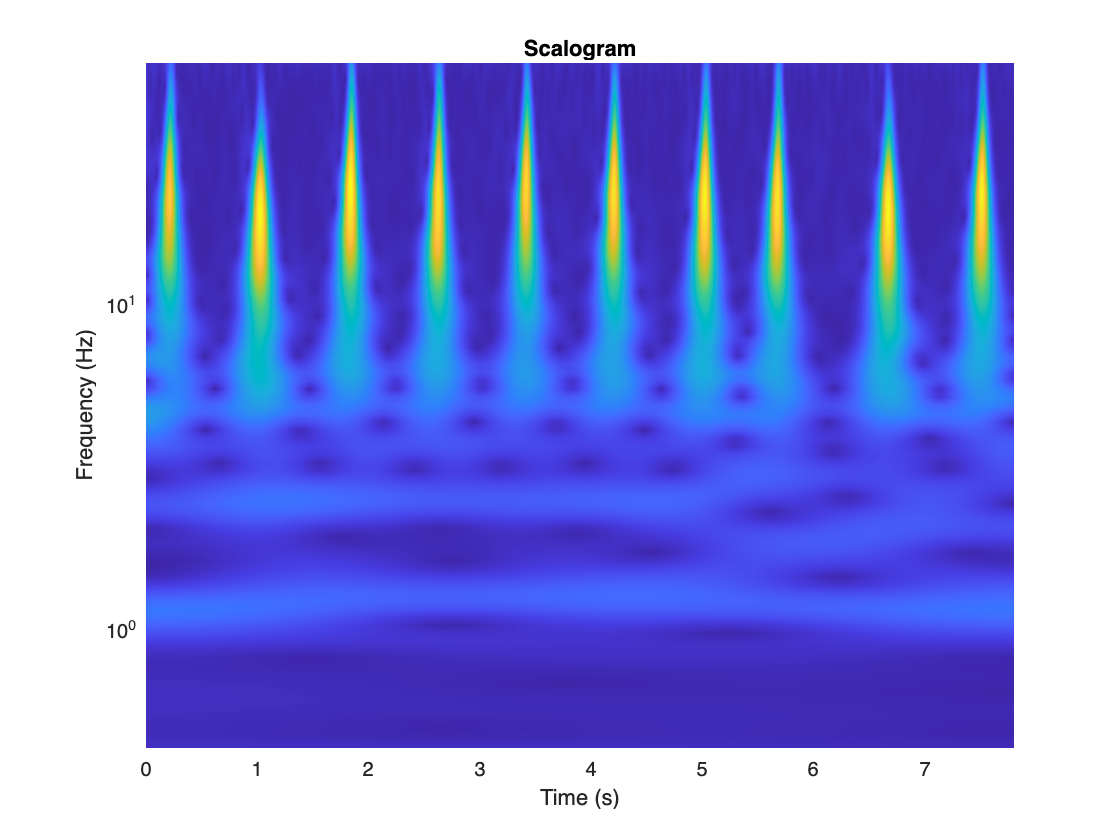

Fs = 128;
fb = cwtfilterbank('SignalLength',1000,...
    'SamplingFrequency',Fs,...
    'VoicesPerOctave',12);
sig = ECGData.Data(1,1:1000);
[cfs,frq] = wt(fb,sig);
t = (0:999)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)')

% helperCreateRGBfromTF(ECGData,parentDir,dataDir)

allImages = imageDatastore(fullfile(parentDir,dataDir),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 130


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 32


### **GoogLeNet**

Importation des données

net = googlenet;

graphs

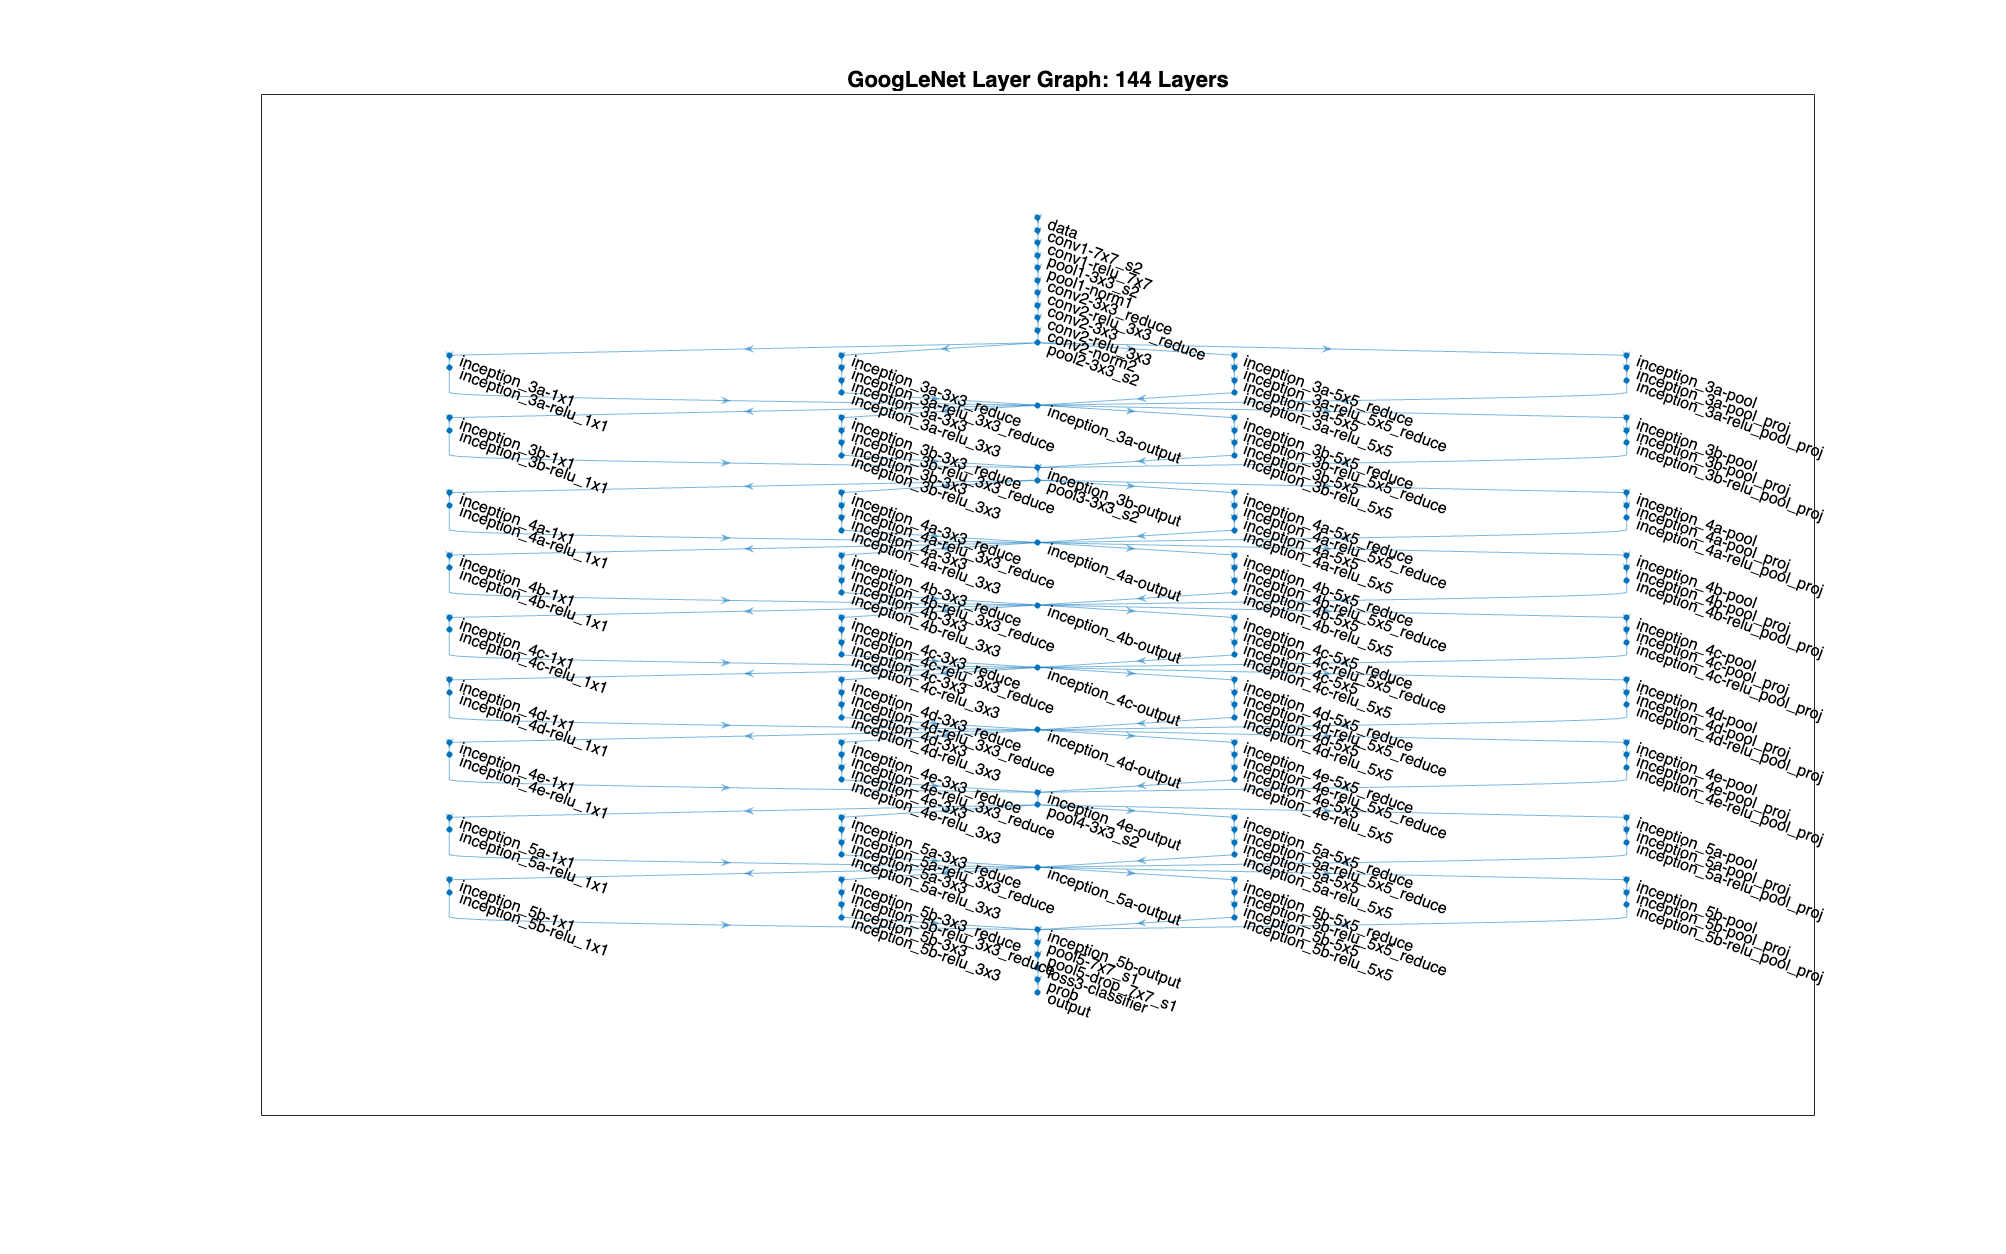

lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


Modification des paramètres, fonction dropout pour prevent l'overfitting

newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:19 |       33.33% |       46.88% |       1.7424 |       1.2343 |      1.0000e-04 |
|       2 |          10 |       00:01:14 |       46.67% |       59.38% |       1.3215 |       1.0273 |      1.0000e-04 |
|       3 |          20 |       00:02:13 |       40.00% |       65.62% |       1.0888 |       0.7984 |      1.0000e-04 |
|       4 |          30 |       00:03:08 |       60.00% |       75.00% |       0.6749 |       0.5232 |      1.0000

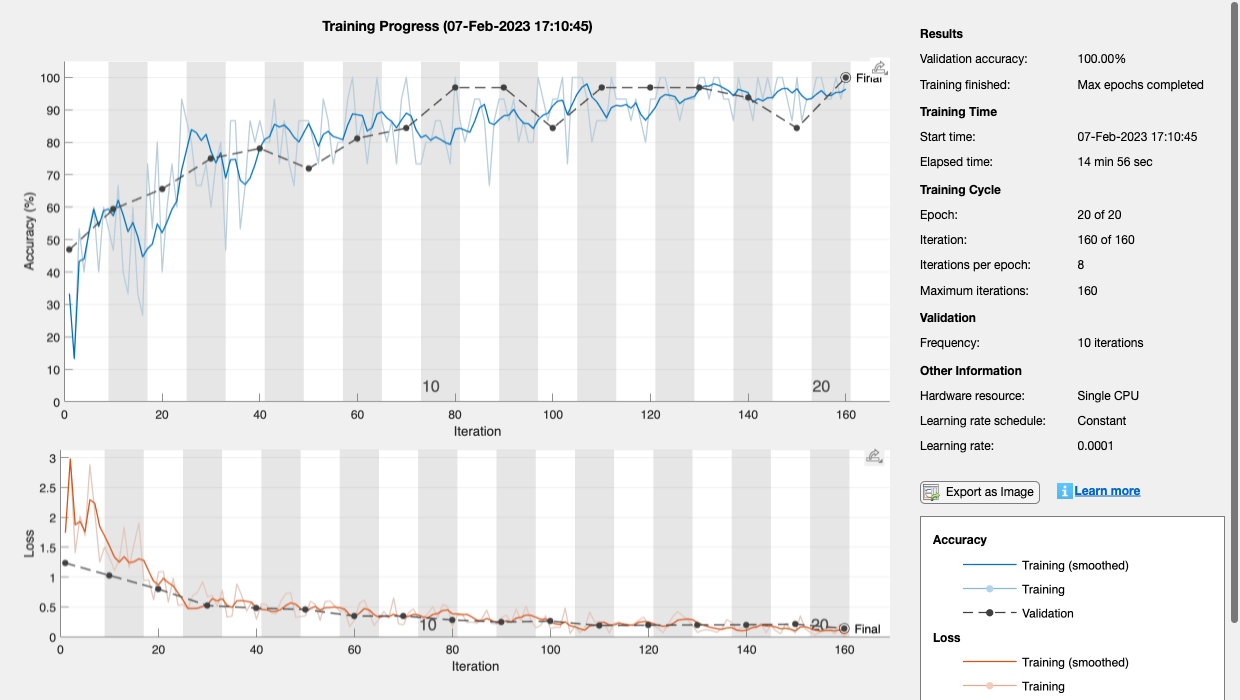

trainedGN = trainNetwork(imgsTrain,lgraph,options);

trainedGN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


[YPred,probs] = classify(trainedGN,imgsValidation);
accuracy = mean(YPred==imgsValidation.Labels);
disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%'])

GoogLeNet Accuracy: 100%


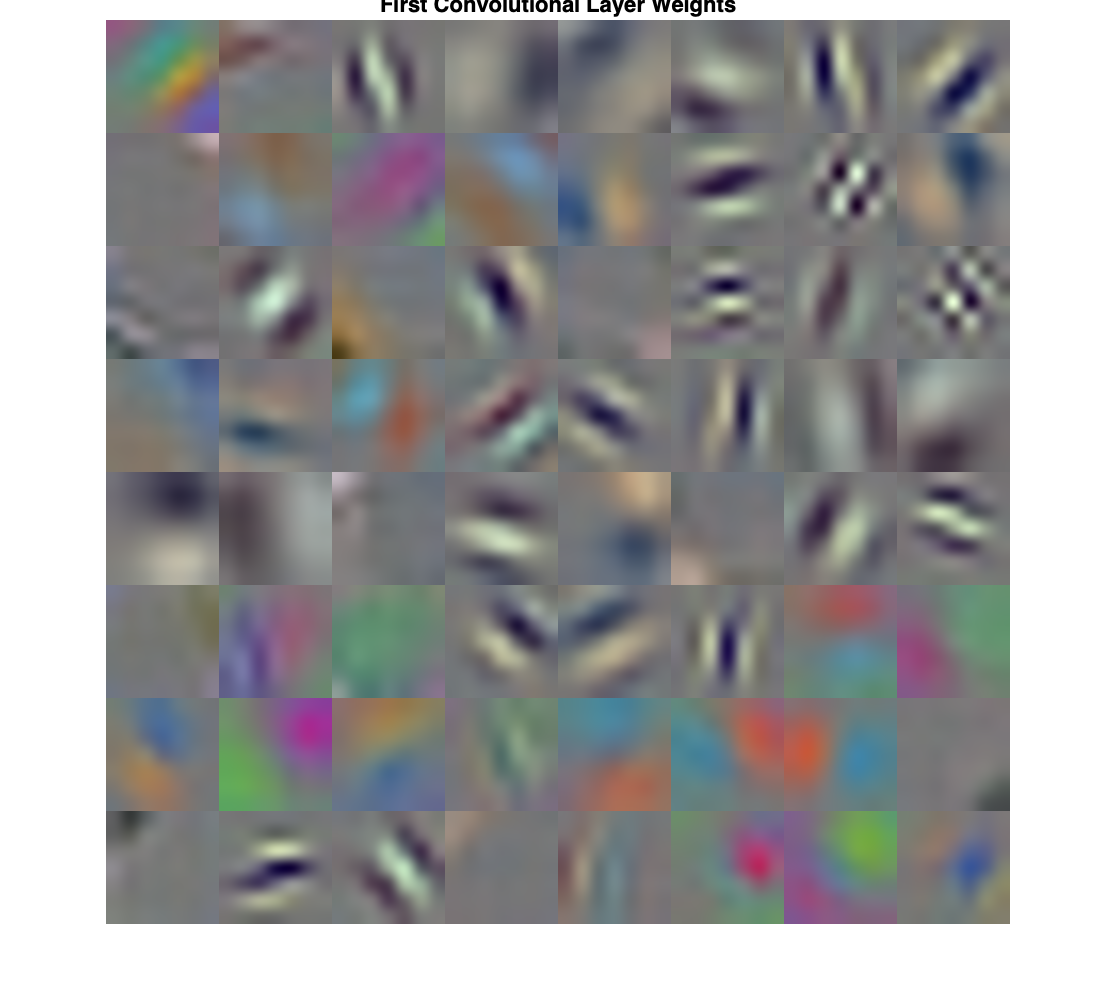

wghts = trainedGN.Layers(2).Weights;
wghts = rescale(wghts);
wghts = imresize(wghts,5);
figure
montage(wghts)
title('First Convolutional Layer Weights')

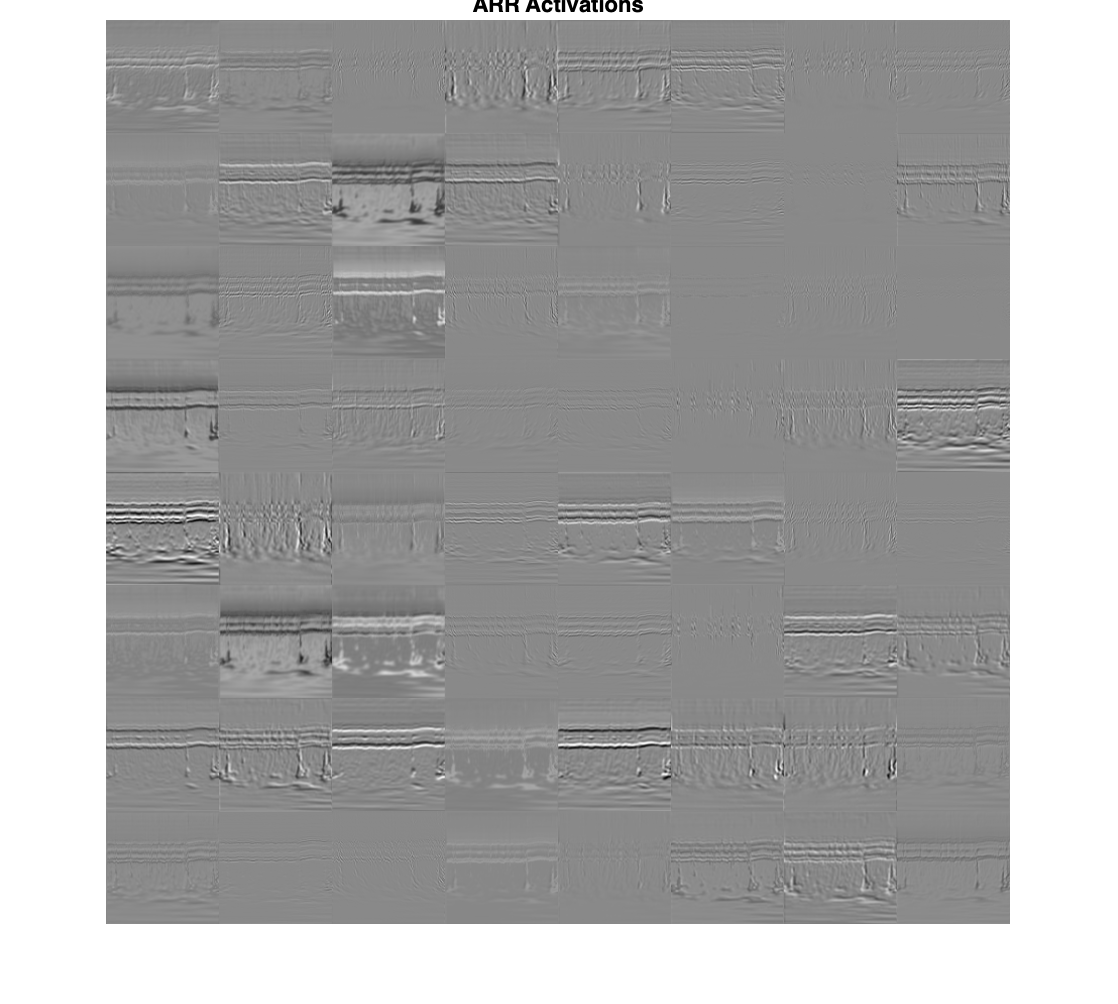

convLayer = 'conv1-7x7_s2';

imgClass = 'ARR';
imgName = 'ARR_10.jpg';
imarr = imread(fullfile(parentDir,dataDir,imgClass,imgName));

trainingFeaturesARR = activations(trainedGN,imarr,convLayer);
sz = size(trainingFeaturesARR);
trainingFeaturesARR = reshape(trainingFeaturesARR,[sz(1) sz(2) 1 sz(3)]);
figure
montage(rescale(trainingFeaturesARR),'Size',[8 8])
title([imgClass,' Activations'])

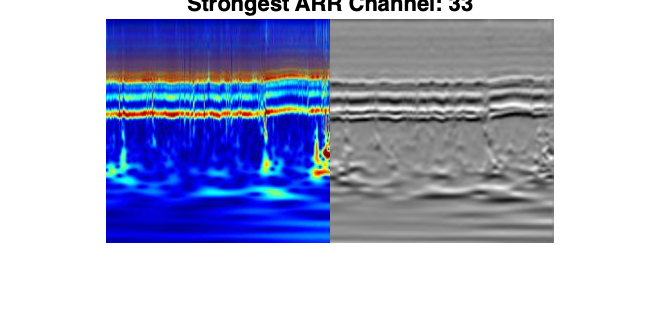

imgSize = size(imarr);
imgSize = imgSize(1:2);
[~,maxValueIndex] = max(max(max(trainingFeaturesARR)));
arrMax = trainingFeaturesARR(:,:,:,maxValueIndex);
arrMax = rescale(arrMax);
arrMax = imresize(arrMax,imgSize);
figure;
imshowpair(imarr,arrMax,'montage')
title(['Strongest ',imgClass,' Channel: ',num2str(maxValueIndex)])